# Create 3D extruded mesh

First, we create a vertical cross section with a single fault and folded stratigraphy. Second, we extrude the cross section to have a 3D computational domain with the correct dimensions (e.g. the dimensions of the experimental sandbox).

Example prepared by Lluis Salo-Salgado ([lsalo@mit.edu](mailto:lsalo@mit.edu))

% Cleanup
clear, close all
mrstModule add upr
mrstVerbose on

% Path for loading datafiles and saving mesh
pth = fullfile(mrstPath('ls-proj'), 'fluidflower/exampleForKundan/mesh/');

% Save data
save_data = false;          % true or false

% Mesh resolution
resolution = 'coarse';      % 'coarse' or 'fine'

% grid depth
depth = '1km';            % '1km' or 'surface' (fluidflower)

% Plotting functionality
fig2D = @() figure('Position', [0,0,800,500]);
fig3D = @() figure('Position', [0,0,1300, 650]);
alpha = 0.6;
cmap  = jet*alpha + (1-alpha);
setAxProps = @(ax) set(ax, 'View'              , [50, 20]         , ...
                           'PlotBoxAspectRatio', [4.40, 1.86, 1.00], ...
                           'Projection'        , 'Perspective'     , ...
                           'Box'               , 'on'              , ...
                           'ColorMap'          , cmap              );

## Load data

We start by loading a data structure that contains points describing the outline, faults, and well positions (see simpleExtrudedMesh_datapoints.m)

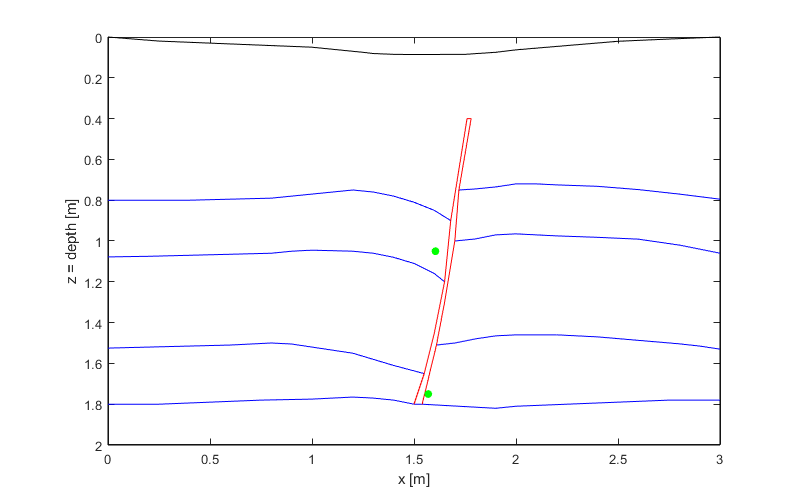

meshpt  = load(fullfile(pth, 'simpleExtrudedMesh_datapoints.mat'));
meshpt  = meshpt.stratiPoints;

% Depth is positive in MRST
meshpt.boundary(:,2) = meshpt.boundary(:,2)*-1;
for n=1:length(meshpt.lines)
    if n <= 2, meshpt.wells{n}(:, 2) = meshpt.wells{n}(:, 2)*-1; end
    meshpt.lines{n}(:, 2) = meshpt.lines{n}(:, 2)*-1;
end

% plot
fig2D(), hold on
plot(meshpt.boundary(:,1), meshpt.boundary(:,2), 'k')
plotLinePath(meshpt.lines(4:end), 'b');
plotLinePath(meshpt.lines(1:3), 'r');
plotLinePath(meshpt.wells, '.g', 'markerSize', 20);
box on, axis equal tight, view([0, -90])
xlabel('x [m]'); ylabel('z = depth [m]')

## Generate 2D PEBI grid

We construct a 2D composite PEBI grid from the datapoints using the upr module of MRST and the constraints imposed by the stratigraphy and fault. The parameter nc controls the number of cells, for an approximation you can do number of cells = 3/cellSize(1) * 2/cellSize(2)

if strcmp(resolution, 'coarse')
    cellSize = [3 3]*1e-2; % cm to m
    fcf      = 0.5;
elseif strcmp(resolution, 'fine')   % about 60k cells
    disp('Generating fine mesh. This could take several minutes.')
    cellSize = [1 1]*1e-2; % cm to m
    fcf      = 1;
end
tic
L   = max(abs(meshpt.boundary));
G2D = compositePebiGrid2D(cellSize, [L(1) L(2)], ...
      'polybdr', meshpt.boundary, ...           % Outline
      'faceConstraints', meshpt.lines, ...      % Fault lines
      'FCFactor'       , fcf          , ...     % Relative size of fault-line cells
      'cellConstraints', meshpt.wells , ...     % Well coordinates
      'interpolateCC'  , false, ...
      'CCFactor'       , 1         ,  ...       % Relative size of well cells
      'interpolateFC'  , true);
G2D = removeShortEdges(G2D, 5e-05); % The grid may contain very short edges.
toc

Elapsed time is 16.199680 seconds.


## Plot 2D grid

Well cells are identified with G.cells.tag = true. We will need the well number later, so we find and store these.

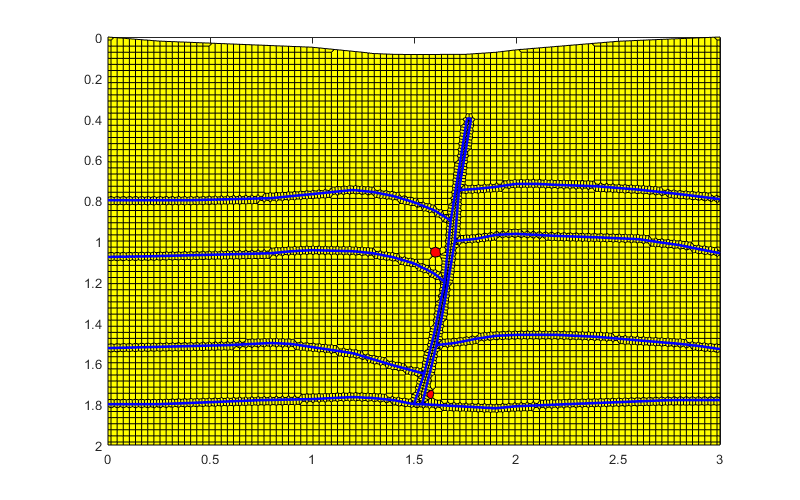

wellNo2D                = nan(G2D.cells.num,1);
wellNo2D(G2D.cells.tag) = 1:nnz(G2D.cells.tag);
fig2D(), plotGrid(G2D); axis equal tight, box on                 % Grid
plotFaces(G2D, G2D.faces.tag, 'edgeColor', 'b', 'lineWidth', 2); % Lines
plotGrid(G2D, G2D.cells.tag , 'faceColor', 'r');                 % Wells
view([0 -90])

## Find regions

The lines divide the reservoir into 9 distinct regions. We identify these using functionality from the coarsegrid module

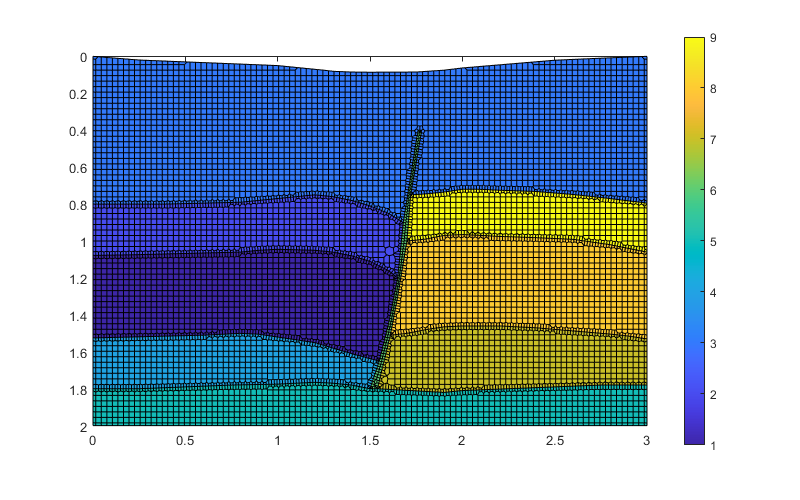

mrstModule add coarsegrid
p = ones(G2D.cells.num,1);
p = processPartition(G2D, p, find(G2D.faces.tag));

% Visualize regions
for n=1:max(p)
   plotCellData(G2D, n*ones(sum(p==n), 1), p==n)
end
view([0 -90])
colorbar

## Extrude (2.5D)

We construct a volumetric reservoir model by extruding the 2D grid. The function makeLayeredGrid uses a 2D grid [x, y] and extrudes to the z dimension (depth). Since we have x and z, we will reorganize our grid's dimensions so that we get the correct z.

% Make layered grid
nLayers = 1;                        % Number of layers
layerThickness = 1e-2*2.5;          % 2.5 cm thick
G = makeLayeredGrid(G2D, nLayers);  % by default 1m thick
G.nodes.coords(G.nodes.coords(:, 3) == 1, 3) = layerThickness;    % update thick
G.nodes.coords = G.nodes.coords(:, [3 1 2]); % x -> y, y -> z, new dim = x
if strcmp(depth, '1km')
    G.nodes.coords(:,3) = G.nodes.coords(:,3) + 1000;
end
G = computeGeometry(G);             % compute cell centroids, etc

Processing Cells    1 : 8206 of 8206 ... done (0.22 [s], 3.75e+04 cells/second)
Total 3D Geometry Processing Time = 0.236 [s]



% Pass cell tags to the grid for later convenience
G.cells.tag = repmat(G2D.cells.tag, nLayers, 1); % hz well cells (all layers)

% Save IDs of wells, layer(s) and compartments 
wellNo       = repmat(wellNo2D, nLayers, 1);
layerID      = reshape(repmat(1:nLayers, G2D.cells.num, 1), [], 1);
compartID    = repmat(p,nLayers,1);

## Save data

if save_data
    nm = [];
    if strcmp(depth, '1km')
        nm = '_depth1km';
    end
    save(fullfile(pth, ['simpleExtrudedG_cellSize' ...                      
                        num2str(cellSize(1)*1e2) 'cm' nm '.mat']), ...
         'G', 'G2D', 'p', 'compartID', 'wellNo', 'layerID')
end

## Plot the resulting layered grid

Here we use darker colors for suggested seal/caprock layers and lighter colors for reservoir layers. The fault here is colored as a conducive (high permeability) structure.

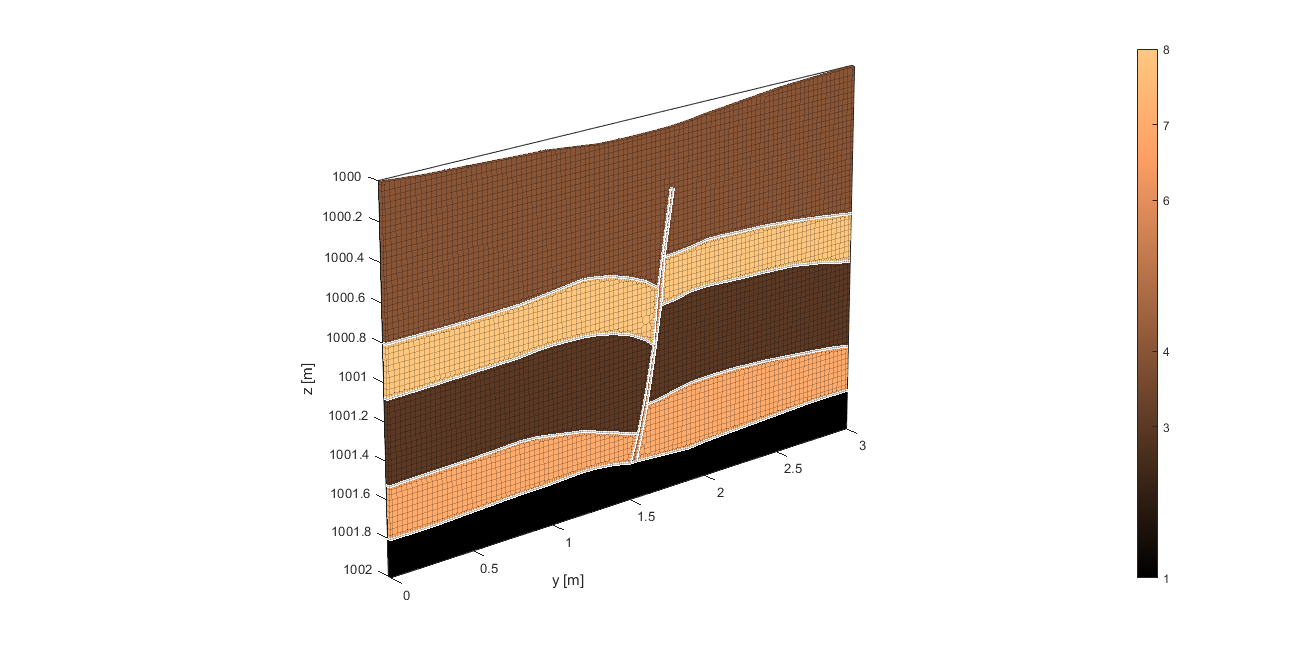

fig3D();
Ncompart = max(p);
cmap = copper(Ncompart);
if strcmp(resolution, 'coarse')
    lyrs = {[1 8], [2 9], [4 7], 3, 5, 6}; % to be modified on a grid to grid basis
elseif strcmp(resolution, 'fine')
    lyrs = {[1 8], [2 9], [4 7], 3, 5, 6};
end
colr = [3, 8, 7, 4, 1, 6];
for n=1:numel(lyrs)
    plotCellData(G, colr(n)*ones(sum(ismember(p, lyrs{n})), 1), ...
                 ismember(p, lyrs{n}), 'edgealpha', 0.2)
end
outlineCoarseGrid(G, compartID,'EdgeColor','w','LineWidth',2);
setAxProps(gca), %camlight();
colormap(copper); c = colorbar; set(c, 'YTick', sort(colr));
axis equal 
xlabel('x [m]'), ylabel('y [m]'), zlabel('z [m]')

%ylim([0 1]), zlim([0 1])